% Script for testing topological domain extraction algorithm.
%
% Reference:
% Hierachicial identification of topological domain via graph Laplacian
% J. Chen, A. O. Hero, I. Rajapakse
%
% Implemented by
% Jie Chen
% http://www.jie-chen.com
% dr.jie.chen@ieee.org

clear,
%close all, clc
load('HiC_chr22_100kb.mat')

% Algorithm selection Alg = 1 or 2
Alg = 1;
% Fiedler value threshold
Threshold = 0.8;

## Load the example data

%load HiC_chr22_100kb

## Remove unmappable region

idx = sum(H)~=0;
H = H(idx,idx);
H = diag(1./sum(H))*H*diag(1./sum(H))*mean(sum(H))^2;

## Apply a transformation

Ht = ceil(H);
% log transformation, and saturated by 6;
Ht = min(log(Ht),6);
% Process -inf, because log(0) = -inf
Ht(Ht == -inf) = -1;
% Shift to be positive
Ht = Ht + 1.001;

% or we can use:
%Ht = sqrt(sqrt(H));

## Call Algorithm

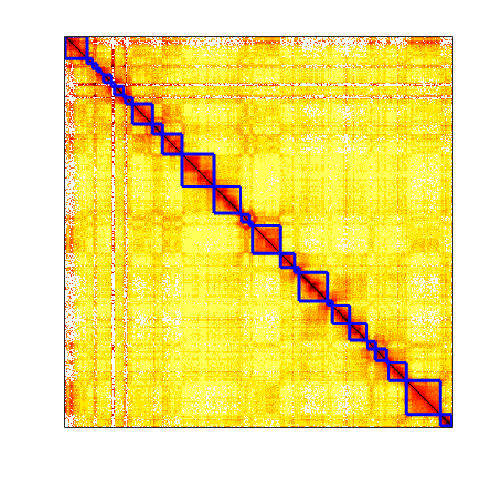

if Alg == 1
    % Algorithm 1
    TAD_boundaries = TAD_Laplace(Ht,Threshold,1,Alg);
elseif Alg ==2
    % Algorithm 2
    % We set a band matrix as a mask
    M = toeplitz([ones(50,1);zeros(size(Ht,1)-50,1)]);
    TAD_boundaries = TAD_Laplace(Ht.*M,Threshold,1,Alg);
end


% Display
Draw_TADs(Ht, TAD_boundaries,[0,6]);